% Moment based kalman filter
clear
close all

datasetFolder="./MRCLAM_Dataset1";
robotNumber = "Robot1";

% true data
groundTruthRaw = importdata(strcat(datasetFolder,"/",robotNumber,"_Groundtruth.dat"));
groundTruth=array2timetable(groundTruthRaw.data(:,2:end), ...
    "RowTimes",seconds(groundTruthRaw.data(:,1)), ...
    "VariableNames",{'trueX','trueY','trueTh'})

groundTruth = 81877×3 timetable
        Time         trueX      trueY     trueTh
    _____________    ______    _______    ______

    1.2483e+09 秒    3.5732    -3.3328    2.3408
    1.2483e+09 秒    3.5732    -3.3328    2.3407
    1.2483e+09 秒    3.5732    -3.3329    2.3408
    1.2483e+09 秒    3.5732    -3.3329    2.3408
    1.2483e+09 秒    3.5732    -3.3329     2.341
    1.2483e+09 秒    3.5732    -3.3329    2.3411
    1.2483e+09 秒    3.5732    -3.3329    2.3411
    1.2483e+09 秒    3.5732    -3.3329    2.3411
    1.2483e+09 秒    3.5733    -3.3328    2.3407
    1.2483e+09 秒    3.5733    -3.3328    2.3406
    1.2483e+09 秒    3.5733    -3.3329    2.3406
    1.2483e+09 秒    3.5733    -3.3329    2.3407
    1.2483e+09 秒    3.5732    -3.3329     2.341
    1.2483e+09 秒    3.5732    -3.3329     2.341
    1.2483e+09 秒    3.5732    -3.3329     2.341
    1.2483e+09 秒    3.5732    -3.3329     2.341


% observation data 
rng('default');
rng(1);
observationMu = 0;
observationSigma = 0.001;
observationNoise = random('Normal',observationMu,observationSigma,[size(groundTruth,1),3]);
observation = groundTruth{:,:}+observationNoise;
observation = array2timetable(observation, ...
    "RowTimes",groundTruth.Time, ...
    "VariableNames",{'obsX','obsY','obsTh'})

observation = 81877×3 timetable
        Time          obsX      obsY      obsTh 
    _____________    ______    _______    ______

    1.2483e+09 秒    3.5726    -3.3326    2.3393
    1.2483e+09 秒    3.5744    -3.3316    2.3414
    1.2483e+09 秒    3.5725    -3.3346    2.3406
    1.2483e+09 秒    3.5721    -3.3329    2.3426
    1.2483e+09 秒    3.5724    -3.3331    2.3418
    1.2483e+09 秒    3.5727    -3.3332    2.3409
    1.2483e+09 秒    3.5726    -3.3313    2.3423
    1.2483e+09 秒    3.5734    -3.3321     2.341
    1.2483e+09 秒    3.5731    -3.3341     2.339
    1.2483e+09 秒    3.5739     -3.332    2.3403
    1.2483e+09 秒    3.5724    -3.3345    2.3397
    1.2483e+09 秒    3.5741    -3.3341    2.3388
    1.2483e+09 秒    3.5717    -3.3325    2.3424
    1.2483e+09 秒    3.5741    -3.3311     2.341
    1.2483e+09 秒     3.573    -3.3336    2.3416
    1.2483e+09 秒    3.5734    -3.3336     2.342


% odometry data
odomRaw = importdata(strcat(datasetFolder,"/",robotNumber,"_Odometry.dat"));
odom = array2timetable(odomRaw.data(:,2:3), ...
    "RowTimes",seconds(odomRaw.data(:,1)), ...
    "VariableNames",{'vel','angVel'});
% dt = seconds(0.01);
% odom = retime(odom,'regular','previous','TimeStep',dt)

% measurement data
measurementRaw = importdata(strcat(datasetFolder,"/",robotNumber,"_Measurement.dat"))

measurementRaw = フィールドをもつ struct :
        data: [5723×4 double]
    textdata: {4×1 cell}


measurement = array2timetable(measurementRaw.data(:,2:4), ...
    "RowTimes",seconds(measurementRaw.data(:,1)), ...
    "VariableNames",{'barcode','range','bearing'});
% measurement.Time = measurement.Time-measurement.Time(1)
landmark_groundTruth = importdata(strcat(datasetFolder,"/","Landmark_Groundtruth.dat"));
landmark_groundTruth = array2table(landmark_groundTruth.data,"VariableNames",{'pole','poleX','poleY','x_std','y_std'})

landmark_groundTruth = 15×5 table
    pole     poleX       poleY       x_std         y_std   
    ____    ________    _______    __________    __________

      6       5.7093      4.964    0.00027464    0.00041465
      7       5.2529     5.5366    0.00011889    0.00035386
      8       3.6999     4.4664    0.00011533    0.00021172
      9       2.3145      3.375    0.00011799    0.00012106
     10       0.4818      4.396    0.00010721    0.00018453
     11       3.1507     2.3829    0.00012614    0.00013848
     12       4.0633    0.94429     6.143e-05    0.00013376
     13       2.6803    0.26835     9.939e-05     9.516e-05
     14      0.94829    0.75601    0.00016941     0.0001512
     15       3.7629    -2.0309    0.00011487    0.00017474
     16       1.6984    -2.0897    0.00012742    0.00014707
     17     0.035962     -2.844     8.695e-05     0.0001075
     18      0.94291    -5.4345    0.00020354    0.00053328
     19       2.5902    -5.5227     4.964e-05    0.00022974
     

barcode = readtable(strcat(datasetFolder,"/","Barcodes.dat"));
barcode = renamevars(barcode,[1,2],{'pole','barcode'});
measurement = innerjoin(measurement,barcode);
measurement = innerjoin(measurement,landmark_groundTruth);
measurement = sortrows(measurement)

measurement = 4771×8 timetable
        Time         barcode    range    bearing    pole    poleX      poleY       x_std         y_std   
    _____________    _______    _____    _______    ____    ______    _______    __________    __________

    1.2483e+09 秒      90       2.148     0.025      16     1.6984    -2.0897    0.00012742    0.00014707
    1.2483e+09 秒      90       2.033     0.024      16     1.6984    -2.0897    0.00012742    0.00014707
    1.2483e+09 秒      90       1.946      0.04      16     1.6984    -2.0897    0.00012742    0.00014707
    1.2483e+09 秒      90       1.826     0.043      16     1.6984    -2.0897    0.00012742    0.00014707
    1.2483e+09 秒      90       1.826     0.043      16     1.6984    -2.0897    0.00012742    0.00014707
    1.2483e+09 秒      90       1.826     0.043      16     1.6984    -2.0897    0.00012742    0.00014707
    1.2483e+09 秒      90       1.782     0.058      16     1.6984    -2.0897    0.00012742    0.00014707
    1.2483e+09 秒     

allData = synchronize(groundTruth,measurement,odom,"union",'previous');
allData = rmmissing(allData); %NaNの行を削除
allData.Time = allData.Time-allData.Time(1) %スタート時間を0にする

allData = 177046×13 timetable
      Time      trueX      trueY     trueTh    barcode    range    bearing    pole    poleX      poleY       x_std         y_std        vel     angVel
    ________    ______    _______    ______    _______    _____    _______    ____    ______    _______    __________    __________    _____    ______

    0 秒        3.4276    -3.2233    2.5192      90       2.148     0.025      16     1.6984    -2.0897    0.00012742    0.00014707    0.067      0   
    0.017 秒    3.4231    -3.2201    2.5181      90       2.148     0.025      16     1.6984    -2.0897    0.00012742    0.00014707    0.067      0   
    0.024 秒    3.4227    -3.2196    2.5185      90       2.148     0.025      16     1.6984    -2.0897    0.00012742    0.00014707    0.067      0   
    0.033 秒    3.4227    -3.2196    2.5185      90       2.148     0.025      16     1.6984    -2.0897    0.00012742    0.00014707    0.067      0   
    0.076 秒      3.42    -3.2175     2.521      90       2.148     

## moment kalman filter

x(0) ~ N((3.573;-3.333;2.341),eig(0.01^2)

dt = 0.1;
allData = retime(allData,'regular','previous','TimeStep',seconds(dt))

allData = 14874×13 timetable
     Time     trueX      trueY     trueTh    barcode    range    bearing    pole    poleX      poleY       x_std         y_std        vel     angVel
    ______    ______    _______    ______    _______    _____    _______    ____    ______    _______    __________    __________    _____    ______

    0 秒      3.4276    -3.2233    2.5192      90       2.148     0.025      16     1.6984    -2.0897    0.00012742    0.00014707    0.067      0   
    0.1 秒      3.42    -3.2175     2.521      90       2.148     0.025      16     1.6984    -2.0897    0.00012742    0.00014707    0.067      0   
    0.2 秒    3.4158    -3.2153    2.5179      90       2.148     0.025      16     1.6984    -2.0897    0.00012742    0.00014707    0.067      0   
    0.3 秒    3.4061    -3.2093     2.518      90       2.148     0.025      16     1.6984    -2.0897    0.00012742    0.00014707    0.067      0   
    0.4 秒    3.4044    -3.2061    2.5243      90       2.148     0.025      16  


% loops = 200;
% M(loops) = struct('cdata',[],'colormap',[]);
% h = figure;
% h.Visible = 'off';
% for i=1:loops
%     plot(landmark_groundTruth.poleX,landmark_groundTruth.poleY,'o','Color','r','MarkerFaceColor','r')
%     hold on
%     plot(allData.trueX(i),allData.trueY(i),'o','Color','k','MarkerSize',15)
%     plot([allData.poleX(i),allData.trueX(i)],[allData.poleY(i),allData.trueY(i)],'b')
%     plot(allData.trueX(1:i),allData.trueY(1:i),'k:')
%     title(strcat('t=',num2str(i)))
%     hold off
% %     xlim([0 6])
% %     ylim([0 6])
%     drawnow
%     M(i) = getframe;
% end

% x = [3.573;-3.333;2.341];
x = [3.428;-3.2233;2.519]

x =     3.4280
   -3.2233
    2.5190


sigma_x = [0.01^2,0,0;0,0.01^2,0;0,0,0.01^2];


x_p = zeros(3,1);
sigma_p = zeros(3,3);

i = 1

i = 1

num = 1000

num = 1000

result = zeros(num,3);
log = array2table(zeros(num,20),'VariableNames',{'time','X','Y','Th','Xp','Yp','Thp','y1','y2','z1','z2','K11','K12','K13','K21','K22','K23','K31','K32','K33'});

for i=1:num
    if rem(i,200)==0
        disp(i)
    end
v = GaussianTPM(allData.vel(i),0.0);
u = GaussianTPM(allData.angVel(i),0);

%Step1
x_app = GaussianMixedTPM3d(x,sigma_x);

%Step2
%eq11,eq15
x_p(1) = x_app.X + v.X*x_app.C*dt;
x_p(2) = x_app.Y + v.X*x_app.S*dt;
x_p(3) = x_app.Th + u.X*dt;
%eq11
sigma_p(1,1) = x_app.X2 + 2*v.X*dt*x_app.XC + v.X2*dt^2*x_app.C2;
sigma_p(1,2) = x_app.XY+v.X*dt*x_app.XS + v.X*dt*x_app.YC+v.X2*dt^2*x_app.CS;
sigma_p(1,3) = x_app.XTh + u.X*dt*x_app.X + v.X*dt*x_app.ThC + u.X*v.X*dt^2*x_app.C;
sigma_p(2,1) = sigma_p(1,2);
sigma_p(2,2) = x_app.Y2 + 2*v.X*dt*x_app.YS + v.X2*dt^2*x_app.S2;
sigma_p(2,3) = x_app.YTh + u.X*dt*x_app.Y + v.X*dt*x_app.ThS + u.X*v.X*dt^2*x_app.S;
sigma_p(3,1) = sigma_p(1,3);
sigma_p(3,2) = sigma_p(2,3);
sigma_p(3,3) = x_app.Th2 + 2*u.X*dt*x_app.Th + u.X2*dt^2;


sigma_p = sigma_p-x_p*x_p';

%Step3
% eq12
x_papp = GaussianMixedTPM3d(x_p,sigma_p);

%Step4
r = allData.range(i);
phi = allData.bearing(i);

y = zeros(2,1);
p_x = allData.poleX(i+1);
p_y = allData.poleY(i+1);
vr = GaussianTPM(1.0,0.01);
vphi = GaussianTPM(0.0,0.0007);

e_ha = p_x*x_papp.C-x_papp.XC + p_y*x_papp.S-x_papp.YS;
e_hb = p_y*x_papp.C-x_papp.YC - p_x*x_papp.S+x_papp.XS;
y(1) = e_ha*vr.X*vphi.CosX - e_hb*vr.X*vphi.SinX;
y(2) = e_hb*vr.X*vphi.CosX + e_ha*vr.X*vphi.SinX;

sigma_yy = zeros(2,2);

e_ha2 = (p_x^2*x_papp.C2-2*p_x*x_papp.XCC+x_papp.XXCC)+(p_y^2*x_papp.S2-2*p_y*x_papp.YSS+x_papp.YYSS)...
    +2*(p_x*p_y*x_papp.CS-p_x*x_papp.YCS-p_y*x_papp.XCS+x_papp.XYCS);
e_hb2 = (p_x^2*x_papp.S2-2*p_x*x_papp.XSS+x_papp.XXSS)+(p_y^2*x_papp.C2-2*p_y*x_papp.YCC+x_papp.YYCC)...
    +2*(p_x*p_y*x_papp.CS-p_x*x_papp.YCS-p_y*x_papp.XCS+x_papp.XYCS);
e_hahb = (p_x*p_y*x_papp.C2-p_x*x_papp.YCC-p_y*x_papp.XCC+x_papp.XYCC)...
    -(p_x^2*x_papp.CS-2*p_x*x_papp.XCS+x_papp.XXCS)+(p_y^2*x_papp.CS-2*p_y*x_papp.YCS+x_papp.YYCS)...
    +(p_x*p_y*x_papp.S2-p_x*x_papp.YSS-p_y*x_papp.XSS+x_papp.XYSS);
sigma_yy(1,1) = e_ha2*vr.X2*vphi.Cos2X - 2*e_hahb*vr.X2*vphi.CosX*vphi.SinX + e_hb2*vr.X2*vphi.Sin2X;
sigma_yy(2,2) = e_hb2*vr.X2*vphi.Cos2X + 2*e_hahb*vr.X2*vphi.CosX*vphi.SinX + e_ha2*vr.X2*vphi.Sin2X;
sigma_yy(1,2)=  e_hahb*vr.X2*vphi.Cos2X + e_ha2*vr.X2*vphi.CosXSinX - e_hb2*vr.X2*vphi.CosXSinX - e_hahb*vr.X2*vphi.Sin2X;
sigma_yy(2,1) = sigma_yy(1,2);

sigma_yy = sigma_yy - y*y';

%Step4-2
e_xha = p_x*x_papp.XC-x_papp.X2C+p_y*x_papp.XS-x_papp.XYS;
e_xhb = p_y*x_papp.XC-x_papp.XYC-p_x*x_papp.XS+x_papp.X2S;
e_yha = p_x*x_papp.YC-x_papp.XYC+p_y*x_papp.YS-x_papp.Y2S;
e_yhb = p_y*x_papp.YC-x_papp.Y2C-p_x*x_papp.YS+x_papp.XYS;
e_thha = p_x*x_papp.ThC-x_papp.XThC+p_y*x_papp.ThS-x_papp.YThS;
e_thhb = p_y*x_papp.ThC-x_papp.YThC-p_x*x_papp.ThS+x_papp.XThS;

sigma_xy = zeros(3,2);
sigma_xy(1,1) = e_xha*vr.X*vphi.CosX-e_xhb*vr.X*vphi.SinX; %x*y1
sigma_xy(1,2) = e_xhb*vr.X*vphi.CosX+e_xha*vr.X*vphi.SinX; %x*y2
sigma_xy(2,1) = e_yha*vr.X*vphi.CosX-e_yhb*vr.X*vphi.SinX; %y*y1
sigma_xy(2,2) = e_yhb*vr.X*vphi.CosX+e_yha*vr.X*vphi.SinX; %y*y2
sigma_xy(3,1) = e_thha*vr.X*vphi.CosX-e_thhb*vr.X*vphi.SinX; %theta*y1
sigma_xy(3,2) = e_thhb*vr.X*vphi.CosX+e_thha*vr.X*vphi.SinX; %theta*y2

sigma_xy = sigma_xy - x_p*y';
K = sigma_xy/(sigma_yy);
% K = ones(3,2);
z = [r*cos(phi);r*sin(phi)];
% K*(z-y);
x = x_p + K*(z-y);
sigma_x = sigma_p - K*sigma_yy*K';
result(i,:) = x';
% 'X','Y','Th','Xp','Yp','Thp','y1','y2','z1','z2','K11','K12','K13','K21','K22','K23','K31','K32','K33'
% log.time(i) = ;
log.X(i) = x(1);
log.Y(i) = x(2);
log.Th(i) = x(3);
log.Xp(i) = x_p(1);
log.Yp(i) = x_p(2);
log.Thp(i) = x_p(3);
log.y1(i) = y(1);
log.y2(i) = y(2);
log.z1(i) = z(1);
log.z2(i) = z(2);
log.K11(i) = K(1,1);
log.K12(i) = K(1,2);
% log.K13(i) = K(1,3);
log.K21(i) = K(2,1);
log.K22(i) = K(2,2);
% log.K23(i) = K(2,3);
log.K31(i) = K(3,1);
log.K32(i) = K(3,2);
% log.K33(i) = K(3,3);

end

   200

   400

   600

   800

        1000



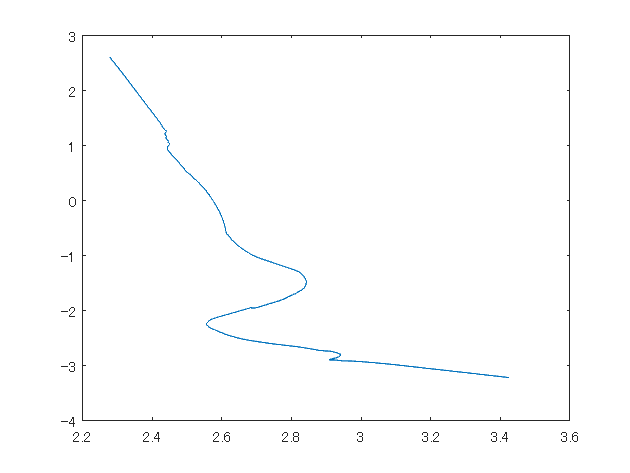

plot(result(:,1),result(:,2))

num2 = num ;
deadReconing = zeros(num2,3);
x = [3.428;-3.2233;2.519]

x =     3.4280
   -3.2233
    2.5190


xt = x(1);
yt = x(2);
tht = x(3);
for ii=1:num2
    v = allData.vel(ii);
    u = allData.angVel(ii);
    xt = xt + v*cos(tht)*dt;
    yt = yt + v*sin(tht)*dt;
    tht = tht + u*dt;
    deadReconing(ii,1) = xt;
    deadReconing(ii,2) = yt;
    deadReconing(ii,3) = tht;
end


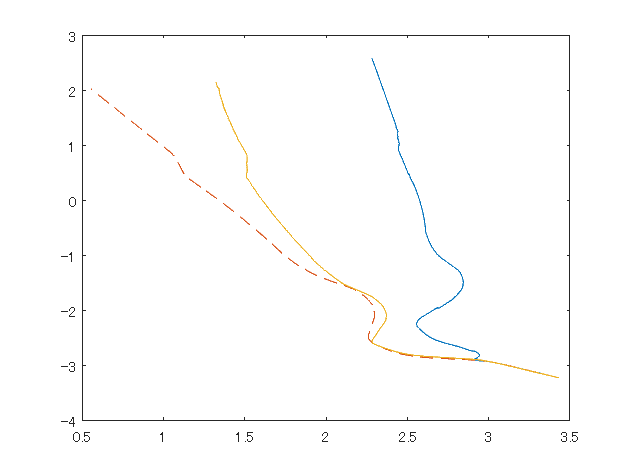

plot(result(:,1),result(:,2))
hold on
plot(deadReconing(:,1),deadReconing(:,2),"--")
plot(allData.trueX(1:num2),allData.trueY(1:num2))
hold off

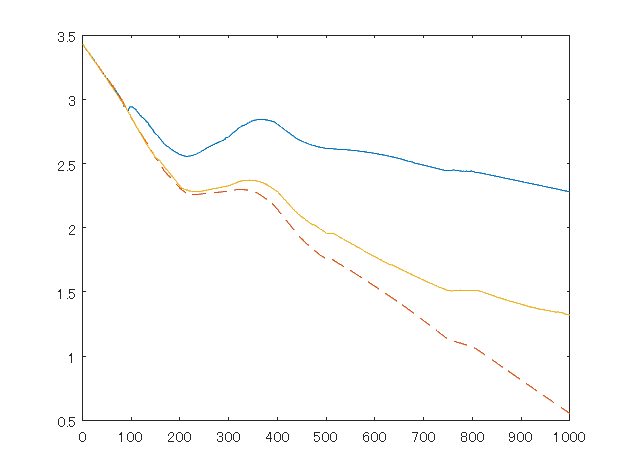

plot(result(:,1))
hold on
plot(deadReconing(:,1),"--")
plot(allData.trueX(1:num2))
hold off

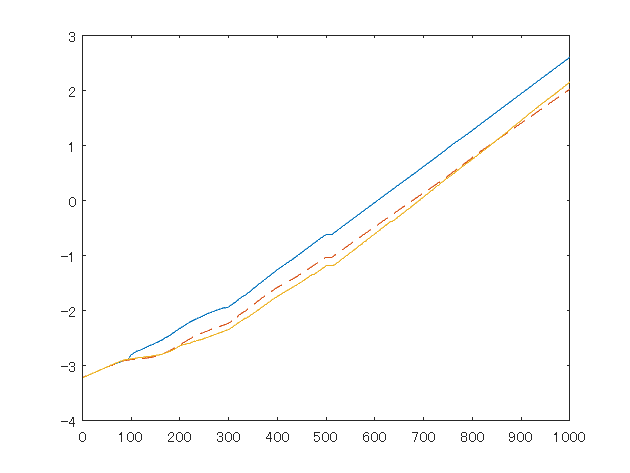


figure()
plot(result(:,2))
hold on
plot(deadReconing(:,2),"--")
plot(allData.trueY(1:num2))
hold off